# Custom Layers Example for Supported DSPC layer.

Example of using Custom layers to model a DSPC supportd bilayer.

Start by making the class and setting it to a custom layers type:

problem = projectClass('Orso lipid example - custom layers');
problem.setModelType('custom layers');
problem.setGeometry('Substrate/liquid');

% First we need to set up a parameters group. We will be using a pre-prepared custom model file, (at the end of the worksheet). Use this to set up the parameters block...

We need to add the relevant parameters we are going to need to define the model (note that Substrate Roughness' always exists as parameter 1..

Parameters = {
    %       Name                min         val         max     fit? 
        {'Oxide thick',         5,          20,         60,     true   };
        {'Oxide Hydration'      0,          0.2,        0.5,    true   };
        {'Lipid APM'            45          55          65      true   };
        {'Head Hydration'       0           0.2         0.5     true   };
        {'Bilayer Hydration'    0           0.1         0.2     true   };
        {'Bilayer Roughness'    2           4           8       true   };
        {'Water Thickness'      0           2           10      true   };
        };
    
 problem.addParamGroup(Parameters);
 problem.setParameter(1,'min',1,'max',10); % Change the substrate roughness limits

Need to add the relevant Bulk SLD's. Change the bulk in from air to silicon, and add two additional water contrasts:

% Change bulk in from air to silicon....
problem.setBulkIn(1,'name','Silicon','min',2.07e-6,'value',2.073e-6,'max',2.08e-6,'fit',false);

% Add two more values for bulk out....
problem.addBulkOut({'SLD SMW',1e-6,2.073e-6,3e-6,true});
problem.addBulkOut({'SLD H2O',-0.6e-6,-0.56e-6,-0.3e-6,true});

problem.setBulkOut(1,'fit',true,'min',5e-6);

Now add the datafiles. We have three datasets we need to consider - the bilayer against D2O, Silicon Matched water and H2O. Load these datafiles in and put them in the data block....

% Read in the datafiles
D2O_data = dlmread('c_PLP0016596.dat');
SMW_data = dlmread('c_PLP0016601.dat');
H2O_data = dlmread('c_PLP0016607.dat');

% Add the data to the project
problem.addData('Bilayer / D2O', D2O_data(:,1:3));
problem.addData('Bilayer / SMW', SMW_data(:,1:3));
problem.addData('Bilayer / H2O', H2O_data(:,1:3));

problem.setData(2,'dataRange',[0.013 0.37]);
problem.setData(3,'dataRange',[0.013 0.37]);
problem.setData(4,'dataRange',[0.013 0.37]);

Add the custom file to the project....

%                          name         filename        language    path
problem.addCustomFile({'DSPC Model', 'customBilayer.m' ,'matlab',  'pwd'});

Also, add the relevant background parameters - one each for each contrast:

% Change the name of the existing parameters to refer to D2O
problem.setBacksPar(1,'name','Backs par D2O','fit',true,'min',1e-10,'max',1e-5,'val',1e-6);

% Add two new backs parameters for the other two..
problem.addBacksPar('Backs par SMW',1e-10,1e-6,1e-5,true);
problem.addBacksPar('Backs par H2O',1e-10,1e-6,1e-5,true);

% And add the two new constant backgrounds..
problem.addBackground('Background SMW','constant','Backs par SMW');
problem.addBackground('Background H2O','constant','Backs par H2O');

% And edit the other one....
problem.setBackgroundValue(1,'name','Background D2O');
problem.setBackgroundValue(1,'value','Backs par D2O');

% Finally modify some of the other parameters to be more suitable values
% for a solid / liquid experiment.

% Set the scalefactor...
problem.setScalefactor(1,'Value',1,'min',0.5,'max',2,'fit',true);

Now add the three contrasts as before:

% D2O contrast..
problem.addContrast('name','Bilayer / D2O',...
    'background','Background D2O',...
    'resolution','Resolution 1',...
    'scalefactor', 'Scalefactor 1',...
    'nbs', 'SLD D2O',...        % This is bulk out ('Nb Subs')
    'nba', 'Silicon',...        % This is bulk in ('Nb Air')
    'data', 'Bilayer / D2O');

% SMW contrast..
problem.addContrast('name','Bilayer / SMW',...
    'background','Background SMW',...
    'resolution','Resolution 1',...
    'scalefactor', 'Scalefactor 1',...
    'nbs', 'SLD SMW',...        % This is bulk out
    'nba', 'Silicon',...        % This is bulk in
    'data', 'Bilayer / SMW');

% SMW contrast..
problem.addContrast('name','Bilayer / H2O',...
    'background','Background H2O',...
    'resolution','Resolution 1',...
    'scalefactor', 'Scalefactor 1',...
    'nbs', 'SLD H2O',...        % This is bulk out
    'nba', 'Silicon',...        % This is bulk in
    'data', 'Bilayer / H2O');

And set the model for each..

problem.setContrastModel(1,'DSPC Model');
problem.setContrastModel(2,'DSPC Model');
problem.setContrastModel(3,'DSPC Model');

Look at the complete model definition before sending it to RAT;

disp(problem)

         ModelType: 'custom layers'
    experimentName: 'Orso lipid example - custom layers'
          Geometry: 'substrate/liquid'

    Parameters: ---------------------------------------------------------------------------------------------- 

    p            Name             Min    Value    Max    Fit? 
    _    _____________________    ___    _____    ___    _____

    1    "Substrate Roughness"     1        3      10    true 
    2    "Oxide thick"             5       20      60    true 
    3    "Oxide Hydration"         0      0.2     0.5    true 
    4    "Lipid APM"              45       55      65    true 
    5    "Head Hydration"          0      0.2     0.5    true 
    6    "Bilayer Hydration"       0      0.1     0.2    true 
    7    "Bilayer Roughness"       2        4

Make a controls block....

controls = controlsDef();
controls.calcSldDuringFit = 'no';
controls.procedure = 'bayes';
controls.nsimu = 7000;
controls.repeats = 3;
controls.parallel = 'points';

disp(controls)

  controlsDef with properties:

            parallel: 'points'
           procedure: 'bayes'
    calcSldDuringFit: 'no'
              method: 'dram'
               nsimu: 7000
            adaptint: 100
              burnin: 100
             repeats: 3



And send this to RAT...

[problem,results] = RAT(problem,controls);

Starting RAT ________________________________________________________________________________________________ 

Running DRAM 

Running loop 1 of 3 
 Bayes: 100.0% [****************************************]

Running loop 2 of 3 Using values from the previous run

 Bayes: 100.0% [****************************************]

Running loop 3 of 3 Using values from the previous run

 Bayes: 100.0% [****************************************]


Elapsed time is 20.368692 seconds.

Finished RAT ______________________________________________________________________________________________ 



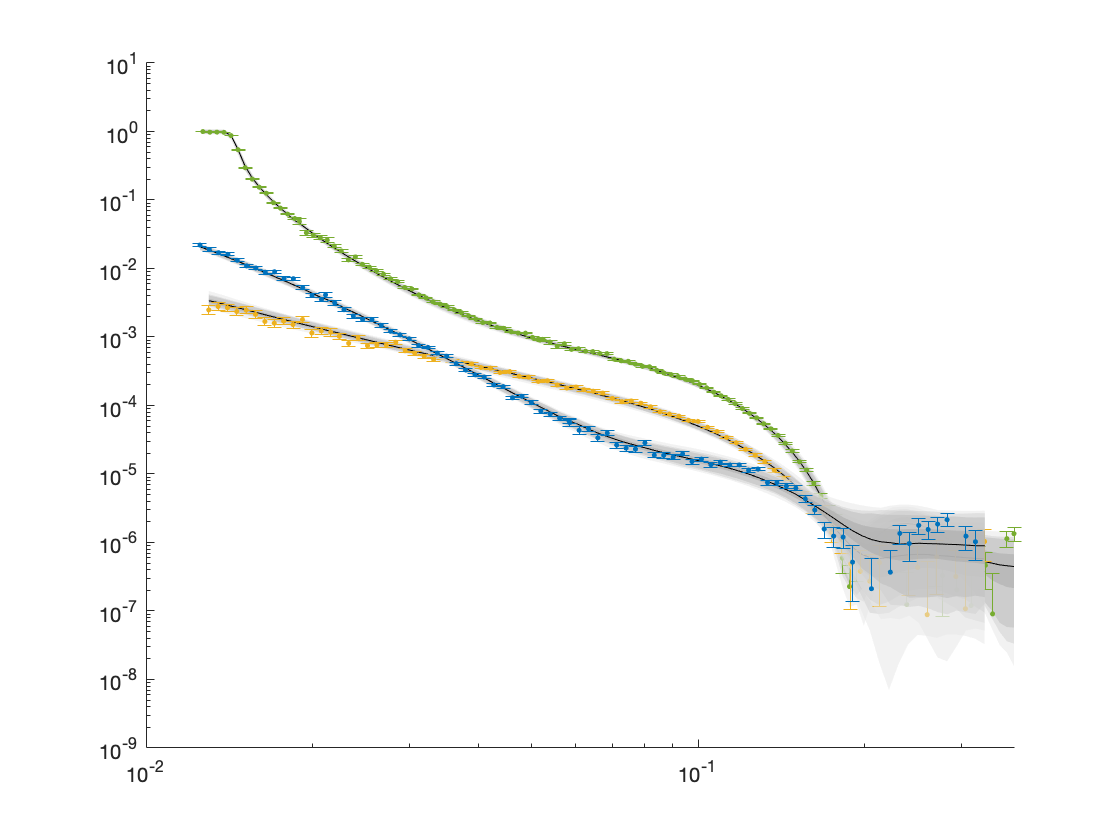

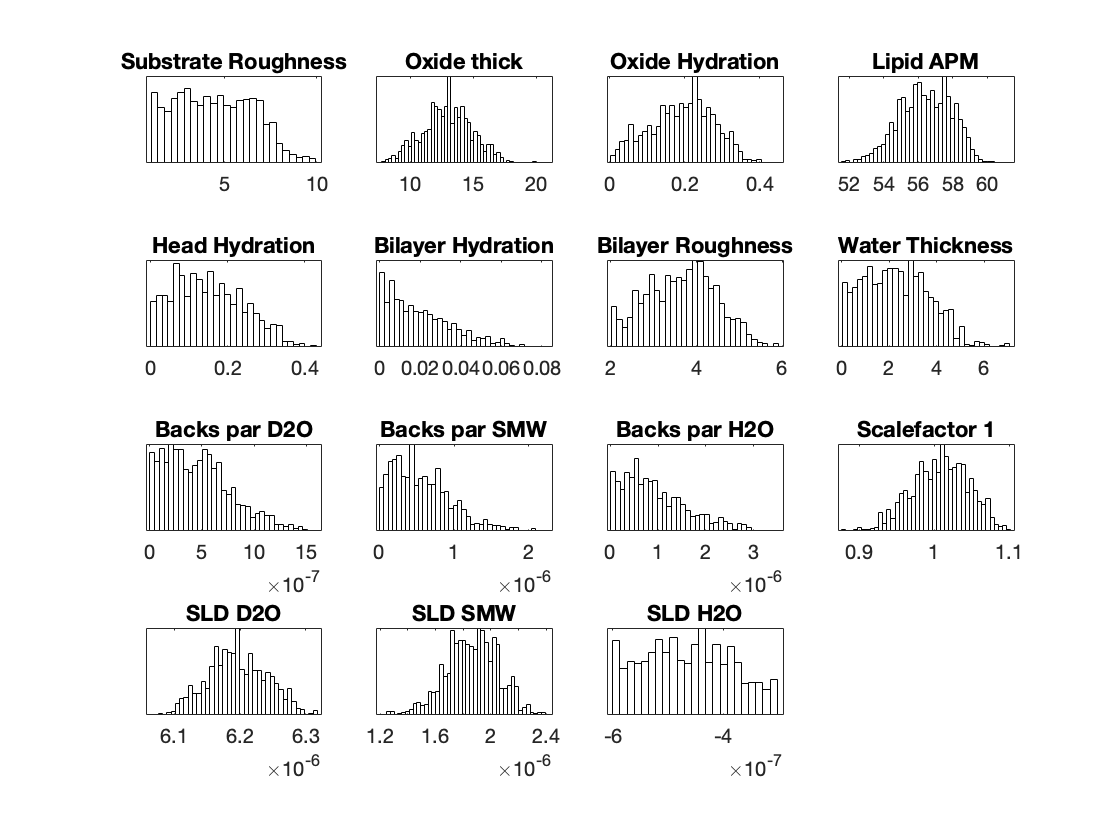

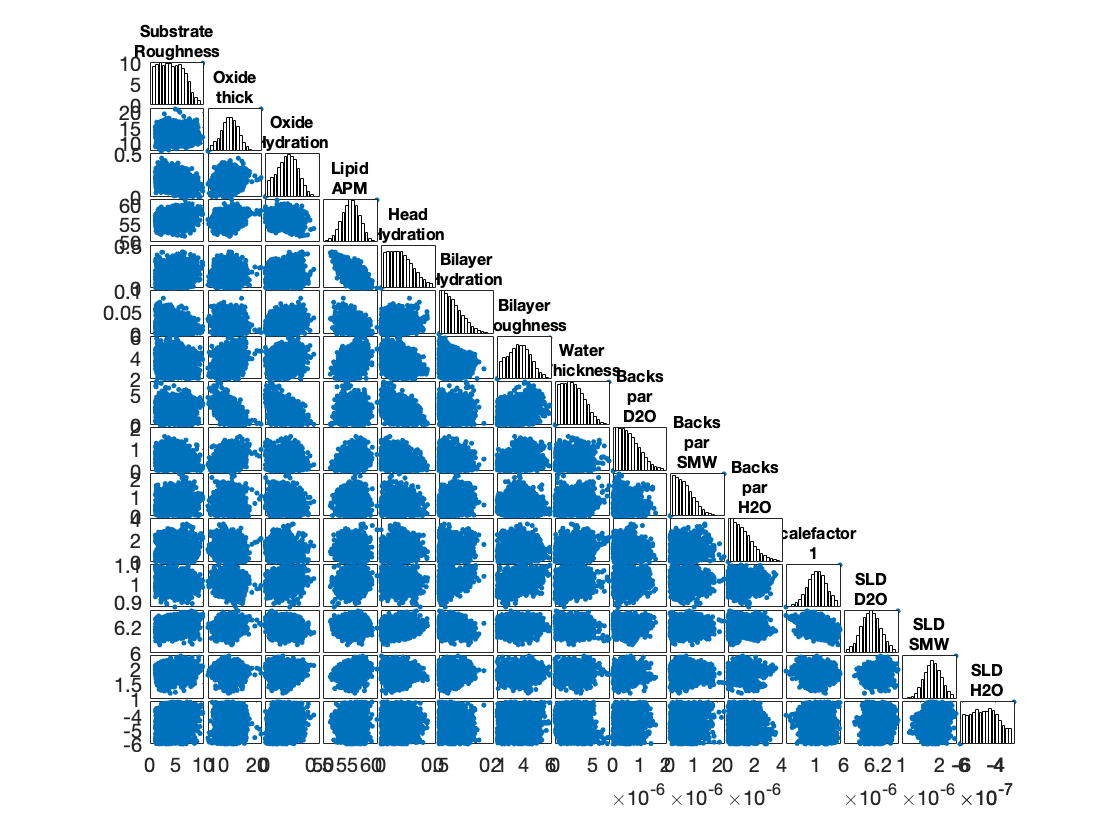


switch controls.procedure
    case 'bayes'
        h2 = figure(2); clf
        sf = results.contrastParams.scalefactors;
        bayesShadedPlot(h2,results.predlims,results.shifted_data,sf);
        
        
        h3 = figure(3); clf
        mcmcplot(results.chain,[],results.fitNames,'hist');
        
         h4 = figure(4); clf; 
         plotBayesCorrFig(results.chain,results.fitNames,h4)

    otherwise
        h2 = figure(2); clf
        plotRefSLD(problem,results)
end

Custom model file:

function [output,sub_rough] = customBilayer(params,bulk_in,bulk_out,contrast)
%CUSTOMBILAYER  RASCAL Custom Layer Model File.
%
%
% This file accepts 3 vectors containing the values for
% Params, bulk in and bulk out
% The final parameter is an index of the contrast being calculated
% The m-file should output a matrix of layer values, in the form..
% Output = [thick 1, SLD 1, Rough 1, Percent Hydration 1, Hydrate how 1
%           ....
%           thick n, SLD n, Rough n, Percent Hydration n, Hydration how n]
% The "hydrate how" parameter decides if the layer is hydrated with
% Bulk out or Bulk in phases. Set to 1 for Bulk out, zero for Bulk in.
% Alternatively, leave out hydration and just return..
% Output = [thick 1, SLD 1, Rough 1,
%           ....
%           thick n, SLD n, Rough n] };
% The second output parameter should be the substrate roughness

sub_rough = params(1);
oxide_thick = params(2);
oxide_hydration = params(3);
lipidAPM = params(4);
headHydration = params(5);
bilayerHydration = params(6);
bilayerRough = params(7);
waterThick = params(8);

% We have a constant SLD for the oxide
oxide_SLD = 3.41e-6;

% Now make the lipid layers..
% Use known lipid volume and compositions
% to make the layers

% define all the neutron b's.
bc = 0.6646e-4;     %Carbon
bo = 0.5843e-4;     %Oxygen
bh = -0.3739e-4;	%Hydrogen
bp = 0.513e-4;      %Phosphorus
bn = 0.936e-4;      %Nitrogen
bd = 0.6671e-4;     %Deuterium

% Now make the lipid groups..
COO = (4*bo) + (2*bc);
GLYC = (3*bc) + (5*bh);
CH3 = (2*bc) + (6*bh);             
PO4 = (1*bp) + (4*bo);
CH2 = (1*bc) + (2*bh);
CHOL = (5*bc) + (12*bh) + (1*bn);

% Group these into heads and tails:
Head = CHOL + PO4 + GLYC + COO;
Tails = (34*CH2) + (2*CH3);

% We need volumes for each.
% Use literature values:
vHead = 319;
vTail = 782;

% we use the volumes to calculate the SLD's
SLDhead = Head / vHead;
SLDtail = Tails / vTail;

% We calculate the layer thickness' from
% the volumes and the APM...
headThick = vHead / lipidAPM;
tailThick = vTail / lipidAPM;

% Manually deal with hydration for layers in
% this example.
oxSLD = (oxide_hydration * bulk_out(contrast)) + ((1 - oxide_hydration) * oxide_SLD);
headSLD = (headHydration * bulk_out(contrast)) + ((1 - headHydration) * SLDhead);
tailSLD = (bilayerHydration * bulk_out(contrast)) + ((1 - bilayerHydration) * SLDtail);

% Make the layers
oxide = [oxide_thick oxSLD sub_rough];
water = [waterThick bulk_out(contrast) bilayerRough];
head = [headThick headSLD bilayerRough];
tail = [tailThick tailSLD bilayerRough];

% And put these together into our layers stack
output = [oxide ; water ; head ; tail ; tail ; head];

end